# pix2pix - Image to Image Translation

## Installation

Run the function `install.m` to ensure that all required files are added to the MATLAB path.

%添加代码路径
clear all
addpath('code');
addpath('tests');

## Training the model

To train a model you need many pairs of images of "before" and "after". The classic example is the [facades dataset](http://cmp.felk.cvut.cz/~tylecr1/facade/) which contains label images of the fronts of buildings, and the corresponding original photo.

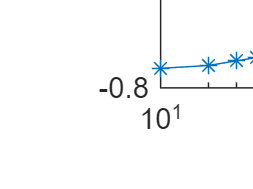

load("C:\data\BaiduSyncdisk\文件与申请工作\论文\2025 棉花荧光迁移学习\matlab script\+data_GreenHouse_TwoEqui\Nor_Data128_GreenHouse_Cate_ReOederTime_OJIPZscore.mat")


%选择数据
Data_PEA=Data_PEA_128;
Data_FP=Data_FP_128;


%SNV预处理
FP_128_STD=std(Data_FP);
FP_128_AVE=mean(Data_FP);
PEA_128_STD=std(Data_PEA);
PEA_128_AVE=mean(Data_PEA);

Data_FP=normalize(Data_FP,'zscore');
Data_PEA=normalize(Data_PEA,'zscore');

%数据预处理
MaxFP=max(Data_FP);
MinFP=min(Data_FP);
MaxPEA=max(Data_PEA);
MinPEA=min(Data_PEA);

%数据对齐,映射至-1到1中
Data_FP=normalize(Data_FP,'range',[-1,1]);
Data_PEA=normalize(Data_PEA,'range',[-1,1]);
Data_PEA(:,119:end)=0;
%展示数据
title('折线图');
xlabel('横坐标');
ylabel('纵坐标');
% 显示网格（可选）
grid on;
semilogx(Time_128,Data_PEA(1,1:end),'-*');
hold on
semilogx(Time_128,Data_FP(1,1:end),'-o');

We will just use the default options which approximately reproduce the setttings from the original pix2pix paper.

%返回训练的结构体
options = p2p.trainingOptions();
%继续训练
%options.ResumeFrom="checkpoints\E500_FtF_FP_PEA_OJIPSNV\p2p_checkpoint_2025-02-17T07-04-56_0550.mat";
options.MaxEpochs=300;

Note training the model will take several hours on a GPU and requires around 4GB of GPU memory.

epoch: 1, it: 2985, G: 2.327107 (L2: 0.009287, GAN: 1.398392), D: 0.345879
epoch: 2, it: 5970, G: 2.453365 (L2: 0.006454, GAN: 1.807984), D: 0.258978
epoch: 3, it: 8955, G: 3.235771 (L2: 0.008640, GAN: 2.371732), D: 0.155358
epoch: 4, it: 11940, G: 3.325594 (L2: 0.005387, GAN: 2.786871), D: 0.092168
epoch: 5, it: 14925, G: 3.999458 (L2: 0.005068, GAN: 3.492662), D: 0.079136
epoch: 6, it: 17910, G: 3.337487 (L2: 0.007064, GAN: 2.631083), D: 0.083072
epoch: 7, it: 20895, G: 3.831664 (L2: 0.005504, GAN: 3.281236), D: 0.070301
epoch: 8, it: 23880, G: 4.006126 (L2: 0.004481, GAN: 3.557997), D: 0.102237
epoch: 9, it: 26865, G: 4.384729 (L2: 0.003790, GAN: 4.005753), D: 0.044967
epoch: 10, it: 29850, G: 4.761834 (L2: 0.005042, GAN: 4.257630), D: 0.054397
epoch: 11, it: 32835, G: 3.724893 (L2: 0.005097, GAN: 3.215240), D: 0.057311
epoch: 12, it: 35820, G: 4.816046 (L2: 0.004458, GAN: 4.370249), D: 0.050998
epoch: 13, it: 38805, G: 4.503354 (L2: 0.008505, GAN: 3.652830), D: 0.053194
epoch: 14, 

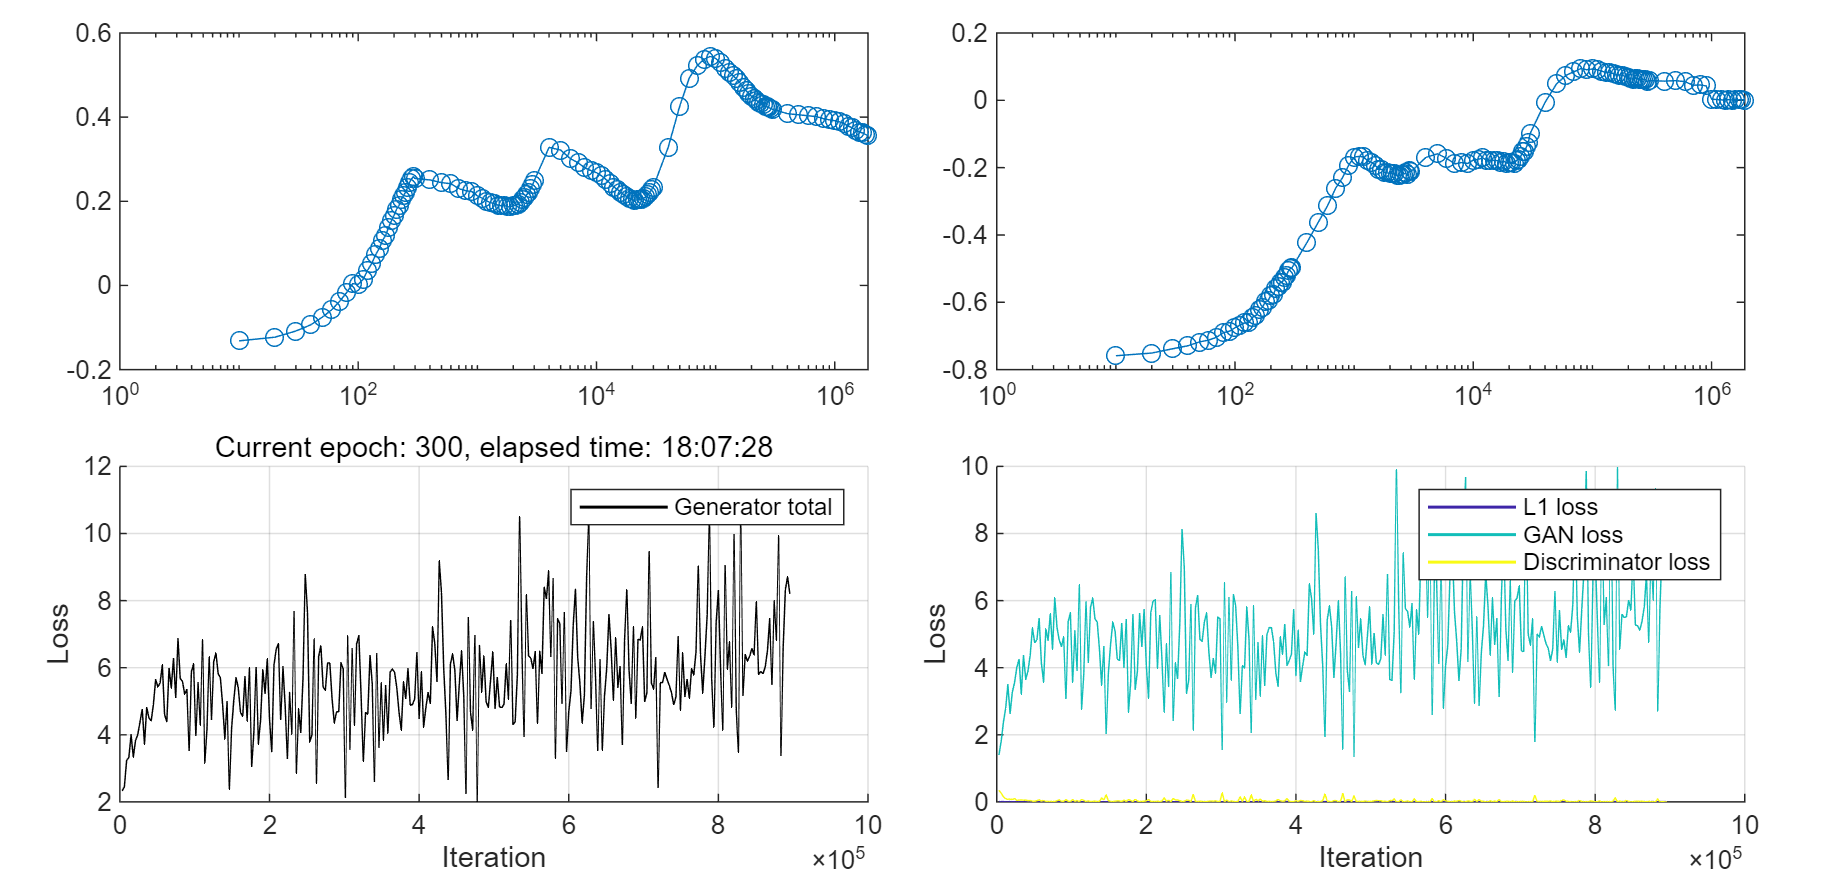

[p2pModel,trainingPlot] = p2p.train(Data_FP, Data_PEA, options, Time_128);

class(trainingPlot)

ans = 'p2p.vis.TrainingPlot'

## Generating images

Once the model is trained we can use the generator to make generate a new image. 

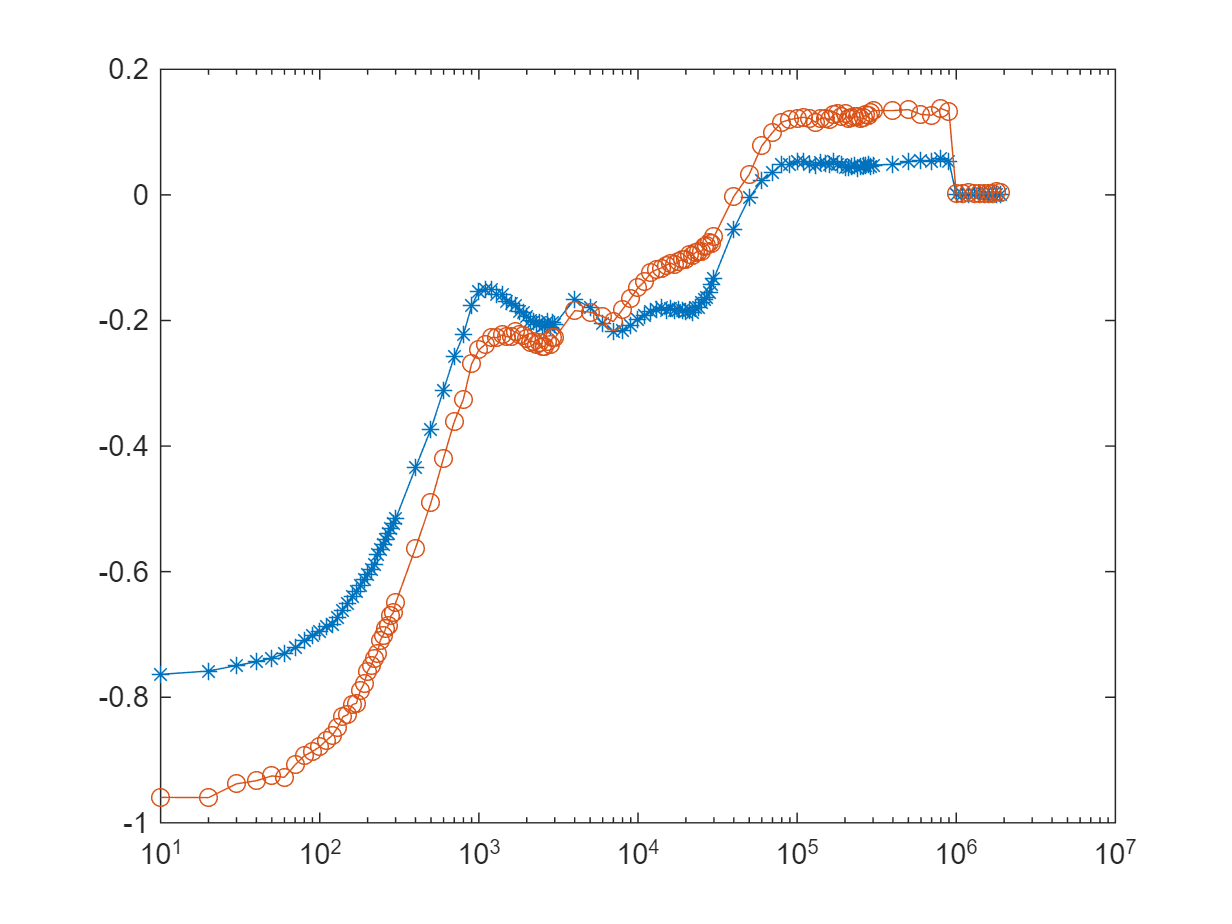

random_integer = randi([0, floor(2985*0.7)]);
exampleInput=Data_FP(random_integer,:);
exampleOutput = p2p.translate(p2pModel, exampleInput');
exampleOutput=double(extractdata(gather(exampleOutput(:,1,1))));
figure
title('折线图');
xlabel('横坐标');
ylabel('纵坐标');
% 显示网格（可选）
grid on;
semilogx(Time_128,Data_PEA(1,:),'-*');
hold on
semilogx(Time_128,exampleOutput,'-o');